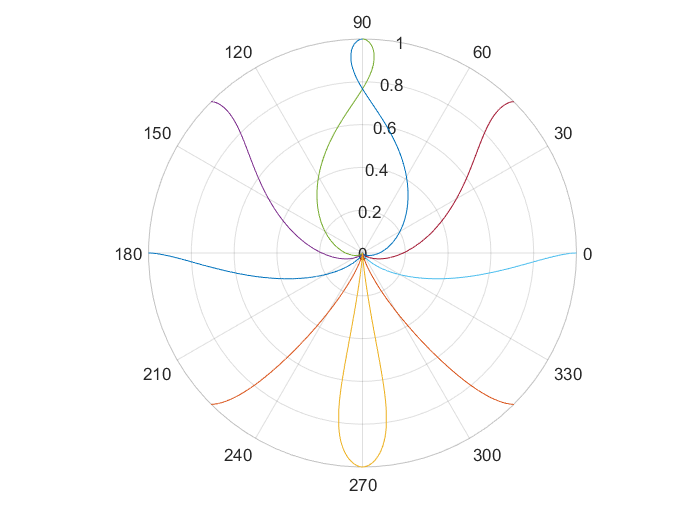

tspan = [0 :0.001: 25];
arr = [0;pi/4;pi/2;-pi/4;-pi/2];
for i = 1:5
    iniCon = [0;0;1;arr(i);pi/2];
    [t, x] = ode45(@(t,x) Dynamic(t,x), tspan, iniCon);
    polarplot(pi+((pi/2)-(x(:,5))+(x(:,4))),x(:,3))
    hold on
end
for i = 1:5
    iniCon = [0;0;1;arr(i);-pi/2];
    [t, x] = ode45(@(t,x) Dynamic(t,x), tspan, iniCon);
    polarplot(pi+((pi/2)-(x(:,5))+(x(:,4))),x(:,3))
    hold on
end
hold off

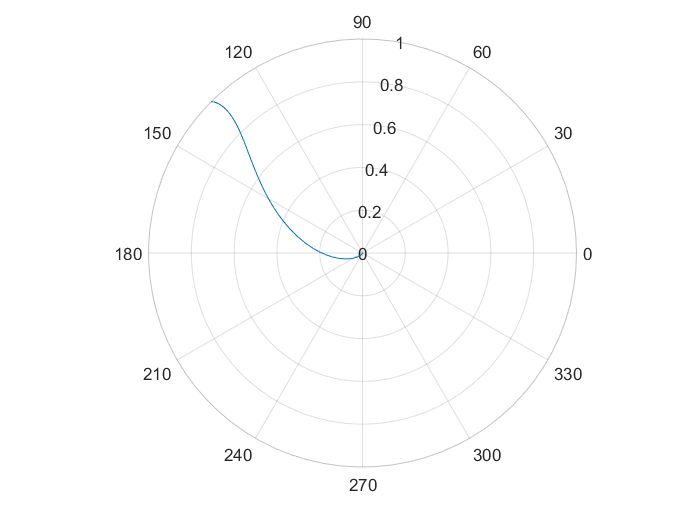

iniCon = [0;0;1;-pi/4;pi/2];
[t, x] = ode45(@(t,x) Dynamic(t,x), tspan, iniCon);
polarplot(pi+((pi/2)-(x(:,5))+(x(:,4))),x(:,3))

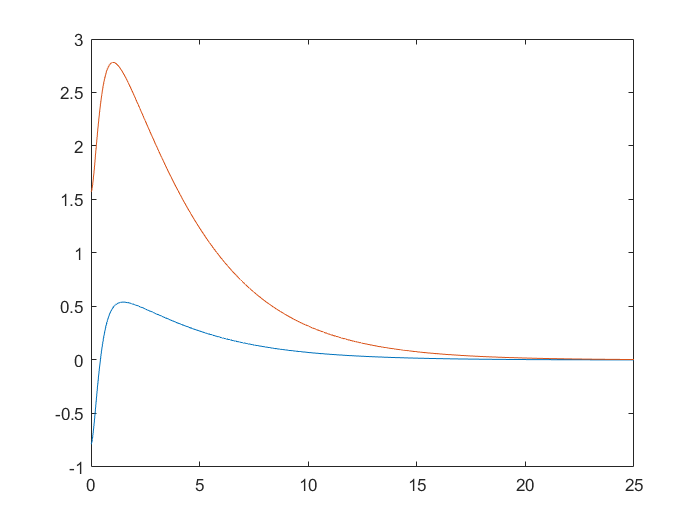

plot(t,x(:,4),t,x(:,5))

function dxdt = Dynamic(t, x)
    Ka = 8;
    Lambda1 = 1.2;
    Lambda2 = 3.5;
    Kp = 1;
    Kf = -1.5;
    dxdt = zeros(5,1);
    dxdt(1) = -Kp*x(1)*cos(x(4)) - Lambda1*(x(1)-Kp*x(3));
    dxdt(2) = Ka*((x(1)*sin(x(4))/x(3))-x(2)) - Kf*x(2) - Lambda2*(x(2)-Ka*x(4)-Kf*x(5));
    dxdt(3) = -x(1)*cos(x(4));
    dxdt(4) = (x(1)*sin(x(4))/x(3))-x(2);
    dxdt(5) = -x(2);
end